## Generate a Fourier series from 2 function pieces

#### First piece

f1 = @(t) cos(t/4);
f1_start_point = 1;
f1_end_point = 3;

#### Second piece

f2 = @(t) t;
f2_start_point = 4;
f2_end_point = 4.5;

#### Calculation requeriments

harmonic_n = 10;        % Matlab is a horrible language and piece of software that performs poorly with lots of recursion. I recommend staying below 255.
harmonic_power_n = 5;   % Number of harmonics to use to calculate the average power.

#### Display parameters

graph_left = 3;
graph_right = 3;

Function definition

% oldparam = sympref ('HeavisideAtOrigin', 1);
u = @(t) heaviside(t);
T = f2_end_point - f1_start_point;

fT = @(t) f1(t).*(u(t - f1_start_point) - u(t - f1_end_point)) + f2(t).*(u(t - f2_start_point) - u(t - f2_end_point));
f = @(t) fT(t - T*floor((t - f1_start_point) / T));

Parameter initialization

w = 2*pi/T;
a_n = zeros(1,harmonic_n+1);
b_n = zeros(1,harmonic_n+1);
a_m = zeros(1,harmonic_n+1);
phi = zeros(1,harmonic_n+1);
c = zeros(1,harmonic_n+1);

Calculation of coeficients $a_n, \ a_m, \ b_n, \ c, \  \varphi$

for n = 0 : harmonic_n     
    a_n(n+1) = (2/T) * integral( @(t)f1(t).*cos(n*w*t), f1_start_point, f1_end_point) + (2/T)*integral(@(t)f2(t).*cos(n*w*t), f2_start_point, f2_end_point);
    b_n(n+1) = (2/T) * integral( @(t)f1(t).*sin(n*w*t), f1_start_point, f1_end_point) + (2/T)*integral(@(t)f2(t).*sin(n*w*t), f2_start_point, f2_end_point);
    
    if abs(a_n(n+1)) < 5*10^(-15)
        a_n(n+1)=0;
    end
             
    if abs(b_n(n+1)) < 5*10^(-15)
        b_n(n+1)=0;
    end

    c(n+1) = ( a_n(n+1) - 1j*b_n(n+1) ) / 2;    
    a_m(n+1) = sqrt( (a_n(n+1))^2 + (b_n(n+1))^2 );
    phi(n+1) = angle( a_n(n+1) - b_n(n+1)*1j );
end 

Partial sum until the nth harmonic of the fourier series

S = @(t) a_n(1)/2;     
for n = 1 : harmonic_n      
    S = @(t) S(t) + a_n(n+1)*cos(n*w*t) + b_n(n+1)*sin(n*w*t);
end

Calculation of average power and amplitude

stem(0:1:harmonic_n, 2*abs(c))

f2 = @(t) f(t).^2;
P = 1 / T * integral(f2, f1_start_point, f2_end_point);
P_k = (a_n(1) / 2)^2;
for n = 2 : harmonic_power_n + 1
    P_k = P_k + (1/2) * (a_m(n))^2;
end

stdout_1 = "Average power = " + P;
stdout_2 = "Percentage of the total average power = " +  (P_k/P)*100 + "%";

Plotting the functions

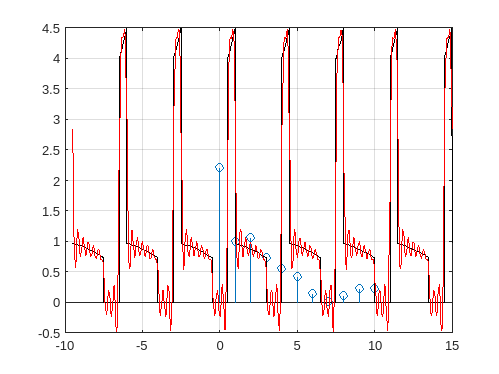

hold on
fplot(f, [f1_start_point - graph_left * T, f2_end_point + graph_right * T], 'k')
I = linspace(f1_start_point - graph_left * T, f2_end_point + graph_right * T, 650);
plot(I, S(I), 'r')
grid on

figure

disp(stdout_1);

Average power = 3.0171


disp(stdout_2);

Percentage of the total average power = 92.9585%



ns = (0:harmonic_n)';
var_table = table(ns, a_n', b_n', c', a_m',phi', 'VariableNames', {'n', 'a_n', 'b_n', 'c_n', 'amplitude', 'phase'});
disp(var_table);

    n         a_n           b_n                c_n              amplitude     phase  
    __    ___________    _________    ______________________    _________    ________

     0         2.2068            0         1.1034+0i              2.2068            0
     1       -0.26301      0.96375        -0.1315+0.48188i       0.99899      -1.8372
     2        -1.0091      0.33379       -0.50456+0.1669i         1.0629      -2.8221
     3       -0.47682     -0.56919       -0.23841-0.2846i        0.74252       2.2681
     4        0.40205     -0.39621        0.20102-0.19811i       0.56447      0.77809
     5        0.38629       0.1652        0.19314+0.082602i      0.42013     -0.40413
     6      0.0089102      0.14787      0.0044551+0.073934i      0.14814      -1.5106
     7    -0.00039299

% oldparam = sympref ('HeavisideAtOrigin', 1);
u = @(t) heaviside(t);

elseif numerotrozos == 3
    %%%PARA FUNCIONES DE 3 TROZOS
    funcion_trozo1 = input('Por favor ingrese la primera función definida en la función a trozos que desea f(t) de trozos: ', 's'); %para poder ingresar la función
    f1_start_point=input("Escribe el valor del punto A de la primera función definida: ");
    f1_end_point=input("Escribe el valor del punto B de la primera función definida: ");

    funcion_trozo2 = input('Por favor ingrese la segunda función definida en la función a trozos que desea f(t): ', 's'); %para poder ingresar la función
    f2_start_point=input("Escribe el valor del punto A de la segunda función definida: ");
    f2_end_point=input("Escribe el valor del punto B de la segunda función definida: ");

    funcion_trozo3 = input('Por favor ingrese la tercera función definida en la función a trozos que desea f(t): ', 's'); %para poder ingresar la función
    PuntoA3=input("Escribe el valor del punto A de la tercera función definida: ");
    PuntoB3=input("Escribe el valor del punto B de la tercera función definida: ");
    
    graph_left=input("Escribe el número de veces que desee ver por la izquierda: ");
    
    graph_right=input("Escribe el número de veces que desee ver por la derecha: ");

    harmonic_n=input("Escribe el número total de harmónicos que quieres obtener (recomedable entre 1 y 200): ");

    harmonic_power_n=input("Escribe hasta qué harmónico querrás analizar la potencia media: "); %Número per teorema de Parseval

    f1 = str2func(['@(t)' funcion_trozo1]);
    f2 = str2func(['@(t)' funcion_trozo2]);
    f3 = str2func(['@(t)' funcion_trozo3]);
    T=PuntoB3-f1_start_point;

    fT = @(t) f1(t).*(u(t-f1_start_point)-u(t-f1_end_point)) + f2(t).*(u(t-f2_start_point)-u(t-f2_end_point))+f3(t).*(u(t-PuntoA3)-u(t-PuntoB3)); %Función de trozos definida con heaviside
    f=@(t) fT(t-T*floor((t-f1_start_point)/T));

    % Calculo de coeficientes SF
    w=2*pi/T;
    a_n=NaN(1,harmonic_n+1); % inicialitzem vectors
    b_n=NaN(1,harmonic_n+1);
    c=NaN(1,harmonic_n+1);
    a_m=NaN(1,harmonic_n+1);
    phi=NaN(1,harmonic_n+1);
    
    for n=0:harmonic_n % calculem els coeficients     
        a_n(n+1)=(2/T)*integral(@(t)f1(t).*cos(n*w*t),f1_start_point,f1_end_point)+(2/T)*integral(@(t)f2(t).*cos(n*w*t),f2_start_point,f2_end_point)+(2/T)*integral(@(t)f3(t).*cos(n*w*t),PuntoA3,PuntoB3);
        b_n(n+1)=(2/T)*integral(@(t)f1(t).*sin(n*w*t),f1_start_point,f1_end_point)+(2/T)*integral(@(t)f2(t).*sin(n*w*t),f2_start_point,f2_end_point)+(2/T)*integral(@(t)f3(t).*sin(n*w*t),PuntoA3,PuntoB3);
             if abs(a_n(n+1))<5*10^(-15)
                 a_n(n+1)=0;
             end
             if abs(b_n(n+1))<5*10^(-15)
                b_n(n+1)=0;
             end
        c(n+1)=(a_n(n+1)-1j*b_n(n+1))/2;  
        a_m(n+1)=sqrt((a_n(n+1))^2+(b_n(n+1))^2);
       phi(n+1)=angle(a_n(n+1)-b_n(n+1)*1j);
    end  % Final càlcul de an i bn
    
    % Suma parcial fins a narmonic de la SF
    
    S = @(t) a_n(1)/2; 
    for n=1:harmonic_n      
        S = @(t) S(t) + a_n(n+1)*cos(n*w*t) + b_n(n+1)*sin(n*w*t);
    end


    hold on
    fplot(f,[f1_start_point-graph_left*T,PuntoB3+graph_right*T],'k') % Graficar para ver cómo queda ft-> f
    I=linspace(f1_start_point-graph_left*T,PuntoB3+graph_right*T,650);
    plot(I,S(I),'r')
    grid on
    
    figure
    stem(0:1:harmonic_n, 2*abs(c)) % Calculant les amplituds amb 2*abs(Cn) i graficar

    % Cálcul de la potencia mitjana TOTAL
    f2=@(t) f(t).^2; % cal vectoritzar la funció f^2
    P=1/T*integral(f2,f1_start_point,PuntoB3); % vigilar si es dos veces la integral o solo una
    stdout="La potencia media P = " +P;
    disp(stdout);

    P_k=(a_n(1)/2)^2;
    for n=2:harmonic_power_n+1
        P_k=P_k+(1/2)*(a_m(n))^2;
    end
    stdout="Porcentage= " +  (P_k/P)*100 + "%" ;
    disp(stdout);
    Yz="Porcentage Pk= " +P_k;
    disp(Yz);

    % Crear tabla con 5 columnas
    tabla = table(a_n', b_n', c', a_m',phi', 'VariableNames', {'an', 'bn', 'cn', 'Amplitud', 'Fase'});

    % Imprimir tabla en la consola
    disp(tabla);

    


elseif numerotrozos == 4
    %%%PARA FUNCIONES DE 4 TROZOS
    funcion_trozo1 = input('Por favor ingrese la primera función definida en la función a trozos que desea f(t) de trozos: ', 's'); %para poder ingresar la función
    f1_start_point=input("Escribe el valor del punto A de la primera función definida: ");
    f1_end_point=input("Escribe el valor del punto B de la primera función definida: ");
    funcion_trozo2 = input('Por favor ingrese la segunda función definida en la función a trozos que desea f(t): ', 's'); %para poder ingresar la función
    f2_start_point=input("Escribe el valor del punto A de la segunda función definida: ");
    f2_end_point=input("Escribe el valor del punto B de la segunda función definida: ");
    funcion_trozo3 = input('Por favor ingrese la tercera función definida en la función a trozos que desea f(t): ', 's'); %para poder ingresar la función
    PuntoA3=input("Escribe el valor del punto A de la tercera función definida: ");
    PuntoB3=input("Escribe el valor del punto B de la tercera función definida: ");
    funcion_trozo4 = input('Por favor ingrese la cuarta función definida en la función a trozos que desea f(t): ', 's'); %para poder ingresar la función
    PuntoA4=input("Escribe el valor del punto A de la cuarta función definida: ");
    PuntoB4=input("Escribe el valor del punto B de la cuarta función definida: ");

    graph_left=input("Escribe el número de veces que desee ver por la izquierda: ");
    
    graph_right=input("Escribe el número de veces que desee ver por la derecha: ");

    harmonic_n=input("Escribe el número total de harmónicos que quieres obtener (recomedable entre 1 y 200): ");

    harmonic_power_n=input("Escribe hasta qué harmónico querrás analizar la potencia media: "); %Número per teorema de Parseval

    f1 = str2func(['@(t)' funcion_trozo1]);
    f2 = str2func(['@(t)' funcion_trozo2]);
    f3 = str2func(['@(t)' funcion_trozo3]);
    f4 = str2func(['@(t)' funcion_trozo4]);
    T=PuntoB4-f1_start_point;

    fT = @(t) f1(t).*(u(t-f1_start_point)-u(t-f1_end_point)) + f2(t).*(u(t-f2_start_point)-u(t-f2_end_point))+f3(t).*(u(t-PuntoA3)-u(t-PuntoB3))+f4(t).*(u(t-PuntoA4)-u(t-PuntoB4)); %Función de trozos definida con heaviside
    f=@(t) fT(t-T*floor((t-f1_start_point)/T));

    %Calculo de coeficientes SF
    w=2*pi/T;
    a_n=zeros(1,harmonic_n+1); %inicialitzem vectors
    b_n=zeros(1,harmonic_n+1);
    c=zeros(1,harmonic_n+1);
    a_m=zeros(1,harmonic_n+1);
    phi=zeros(1,harmonic_n+1);
    
   
    for n=0:harmonic_n %calculem els coeficients     
        a_n(n+1)=(2/T)*integral(@(t)f1(t).*cos(n*w*t),f1_start_point,f1_end_point)+(2/T)*integral(@(t)f2(t).*cos(n*w*t),f2_start_point,f2_end_point)+(2/T)*integral(@(t)f3(t).*cos(n*w*t),PuntoA3,PuntoB3)+(2/T)*integral(@(t)f4(t).*cos(n*w*t),PuntoA4,PuntoB4);
        b_n(n+1)=(2/T)*integral(@(t)f1(t).*sin(n*w*t),f1_start_point,f1_end_point)+(2/T)*integral(@(t)f2(t).*sin(n*w*t),f2_start_point,f2_end_point)+(2/T)*integral(@(t)f3(t).*sin(n*w*t),PuntoA3,PuntoB3)+(2/T)*integral(@(t)f4(t).*sin(n*w*t),PuntoA4,PuntoB4);
        if abs(a_n(n+1))<5*10^(-15)
           a_n(n+1)=0;
        end
        if abs(b_n(n+1))<5*10^(-15)
           b_n(n+1)=0;
        end
    a_m(n+1)=sqrt((a_n(n+1))^2+(b_n(n+1)));
    phi(n+1)=angle(a_n(n+1)-b_n(n+1)*1j);
    c(n+1)=(a(n+1)-1j*b(n+1))/2;  
    end 
    
    %Suma parcial fins a narmonic de la SF
    
    S = @(t) a_n(1)/2; 
    for n=1:harmonic_n      
        S = @(t) S(t) + a_n(n+1)*cos(n*w*t) + b_n(n+1)*sin(n*w*t);
    end


    hold on
    fplot(f,[f1_start_point-graph_left*T,PuntoB4+graph_right*T],'k') %Graficar para ver cómo queda ft-> f
    I=linspace(f1_start_point-graph_left*T,PuntoB4+graph_right*T,650);
    plot(I,S(I),'r')
    grid on

    figure
    stem (0:1:harmonic_n, 2*abs(c)) %Calculant les amplituds amb 2*abs(Cn) i graficar

    %Cálcul de la potencia mitjana TOTAL
    f2=@(t) f(t).^2;%cal vectoritzar la funció f^2
    P=1/T*integral(f2,f1_start_point,PuntoB4); %vigilar si es dos veces la integral o solo una
    stdout="La potencia media P = " +P;
    disp(stdout);

    P_k=c(1)^2;
    for n=2:harmonic_power_n+1
        P_k=P_k+2*abs(c(n))^2;
    end
    stdout="Porcentage= " +  (P_k/P)*100 + "%" ;
    disp(stdout);
    Yz="Porcentage Pk= " +P_k;
    disp(Yz);


    % Crear tabla con 5 columnas
    tabla = table(a_n', b_n', c', a_m',phi', 'VariableNames', {'an', 'bn', 'cn', 'Amplitud', 'Fase'});

    % Imprimir tabla en la consola
    disp(tabla);

    
    
    end 